# Spike Count Analysis

Spiking actvitiy of neurons is the main focus of the [Steinmetz et al, 2019 paper](https://www.nature.com/articles/s41586-019-1787-x). With the rich dataset that they collected during their experiments many analyses are possible that can link neural activity to behavioral or experimental variables.

This notebook is dedicated to working with multi-dimensional data stored in matrix format and how to extract poignant information from large, complex datasets.

### TODO UPDATE SCIEBO LINK!!!! Download Data 

userpath(fullfile(fileparts(matlab.desktop.editor.getActiveFilename), "src"))
%download_from_sciebo('https://uni-bonn.sciebo.de/s/YT3iaH9Po0LJMxR', 'data/steinmetz_2017-12-05_Lederberg.nc')
addpath(fullfile(fileparts(matlab.desktop.editor.getActiveFilename), "data"))

### Load in Data

data = load("data/2017-12-05_Lederberg.mat")

data = struct with fields:
     spike_counts: [250×340×698 int8]
      brain_areas: [698×1 string]
            trial: [340×1 int32]
             cell: [698×1 int32]
             time: [250×1 double]
    response_type: [340×1 double]


spike_counts = data.spike_counts;
brain_areas = data.brain_areas;
trials = data.trial;
cells = data.cell;
time = data.time;
response_types = data.response_type;

## Slicing Matrices:  Finding Neural Spikes

Spiking activity in this dataset is stored as a 3-dimensional matrix. 

Let's slice up this matrix to understand the dimensions of the experiment and explore neural activity.

**Example Exercise**

What are the dimensions of the data stored in the variable `trials`?

size(trials)

ans =    340     1


**Exercises**

What are the dimensions of the data stored in the variable **cells**?

size(cells)

ans =    698     1


What are the dimensions of the data stored in the variable **time**?

size(time)

ans =    250     1


What are the dimensions of the data stored in the variable `spike_counts`?

size(spike_counts)

ans =    250   340   698


Which experimental aspects do the dimensions of `spike_counts `correspond to? **Hint- **use the results of the previous exercises to help you

% 1st dimension is time - 250 points
% 2nd dimension is trial - 340 points
% 3rd dimension is cell - 698 points

What are the dimensions of the data in `brain_areas` and what do they correspond do?

size(brain_areas)

ans =    698     1


% 698 points, one for each cell

Which brain areas were recorded in this dataset?

unique(brain_areas)

ans = 5×1 string array
    "hippocampus"
    "non-visual cortex"
    "root"
    "thalamus"
    "visual cortex"


What brain area is cell 3 in?

brain_areas(3)

ans = "visual cortex"

Find the spike counts over time and trials for cell 3. Name this result `spike_counts_cell_3`

spike_counts_cell_3=spike_counts(:,:,3)

spike_counts_cell_3 = 250×340 int8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0
   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

What are the dimensions of `spike_counts_cell_3 `?

size(spike_counts_cell_3)

ans =    250   340


Plot  `spike_counts_cell_3` as an image and describe what you see in the data.

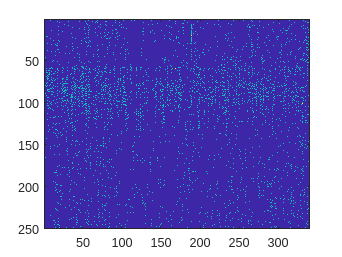

image(spike_counts_cell_3, 'CDataMapping','scaled')

 Remake the above plot but for cell number 30. What differences do you notice and why? 

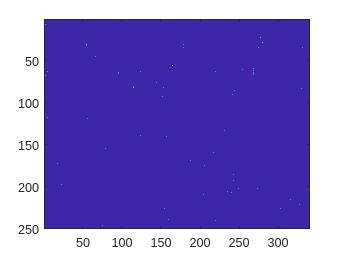

dd=spike_counts(:,:,30);
image(dd, 'CDataMapping','scaled')

What area of the brain are the cells 29-31 located in?

brain_areas(29:31)

ans = 3×1 string array
    "hippocampus"
    "hippocampus"
    "hippocampus"


Find the spike counts for the cells 29-31. Name this `chosen_spikes`

chosen_spikes=spike_counts(:,:,29:31);

What are the dimensions of `chosen_spikes`?

size(chosen_spikes)

ans =    250   340     3


Show the data in `chosen_spikes` as 3 subplots

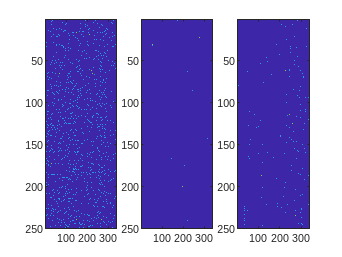

subplot(1,3,1)
image(chosen_spikes(:,:,1), 'CDataMapping','scaled')

subplot(1,3,2)
image(chosen_spikes(:,:,2), 'CDataMapping','scaled')

subplot(1,3,3)
image(chosen_spikes(:,:,3), 'CDataMapping','scaled')

Add a title to each subplot showing the cell number

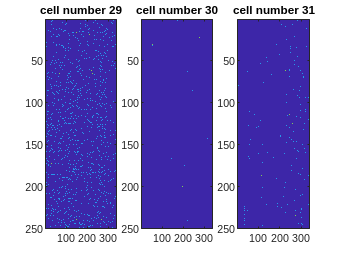

subplot(1,3,1)
image(chosen_spikes(:,:,1), 'CDataMapping','scaled')
title("cell number 29")

subplot(1,3,2)
image(chosen_spikes(:,:,2), 'CDataMapping','scaled')
title("cell number 30")

subplot(1,3,3)
image(chosen_spikes(:,:,3), 'CDataMapping','scaled')
title("cell number 31")

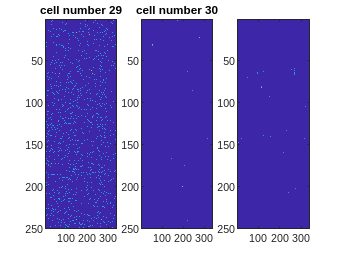

chosen_spikes=spike_counts(:,:,573:581);
sum_chosen_spikes = sum(dd, 3);
image(sum_chosen_spikes, 'CDataMapping','scaled')

Find the spike data from` spike_counts` that represents trial number 99

spike_counts(:,99,:)

ans = 250×1×698 int8 array
ans(:,:,1) =

   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0

Reshape the data from trial number 99 into a 2D matrix and plot it as an image

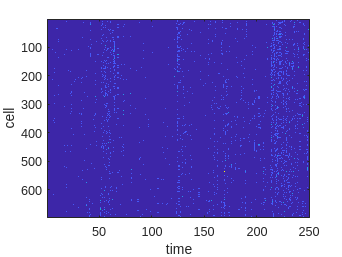

dd=reshape(spike_counts(:,99,:), 698,[]);
clf
image(dd, 'CDataMapping','scaled')
xlabel('time')
ylabel('cell')

Reshape the data from trial number 35 into a 2D matrix and plot it as an image

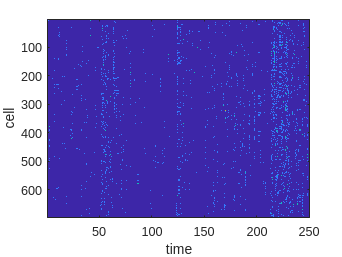

dd=reshape(spike_counts(:,35,:), 698,[]);
clf
image(dd, 'CDataMapping','scaled')
xlabel('time')
ylabel('cell')

Select the data from trials 10, 87 and 314 from `spike_counts`. Name this `spike_counts_chosen_trials`

spike_counts_chosen_trials=spike_counts(:,[10,87,314],:)

spike_counts_chosen_trials = 250×3×698 int8 array
spike_counts_chosen_trials(:,:,1) =

   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   0   0   0
   

What are the dimensions of `spike_counts_chosen_trials `?

size(spike_counts_chosen_trials)

ans =    250     3   698


Using subplots, visualise the data in `spike_counts_chosen_trials`

Below is an example of how to use subplots.

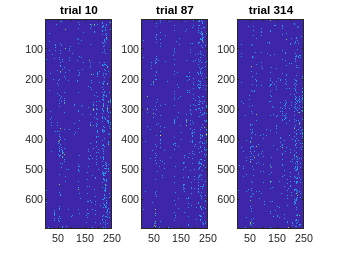

clf
subplot(1,3,1)
image(reshape(spike_counts_chosen_trials(:,1,:),698,[]), 'CDataMapping','scaled')
title("trial 10")

subplot(1,3,2)
image(reshape(spike_counts_chosen_trials(:,2,:),698,[]), 'CDataMapping','scaled')
title("trial 87")

subplot(1,3,3)
image(reshape(spike_counts_chosen_trials(:,3,:),698,[]), 'CDataMapping','scaled')
title("trial 314")

Do you notice a difference between the three chosen trials? They are the trials with the most, closest to average and least number of spikes respectively! But shown like this, we can hardly tell them apart. 

It's time to analyse the spike data in more depth!

## Extracting Averages from Matrices: Neural Activity in Different Brain Areas

Averages are a helpful way of reducing the dimensionality of data to extract essential statistics from large and complex datasets.

In this section we will be averaging our spike counts matrix to investigate which brain areas are the most active.

**Example Exercise**

Calculate the mean spike count per time bin. ie. over the 1st dimension

mean(spike_counts, 1)

ans = ans(:,:,1) =

    0.0440    0.0720    0.0520    0.0560    0.0200    0.0120    0.0040         0    0.0040    0.0040    0.0040    0.0080    0.0040         0         0         0         0         0         0         0    0.0040    0.0040    0.0120    0.0080         0    0.0040         0    0.0040    0.0120    0.0040         0    0.0120    0.0360    0.0280    0.0520    0.0400    0.0440    0.0600    0.0400    0.0560    0.0520    0.0680    0.0560    0.0200    0.0400         0    0.0080         0         0         0         0         0         0    0.0040         0         0    0.0080         0    0.0120         0    0.0080         0    0.0120         0         0         0         0         0         0         0         0         0    0.0040    0.0040         0         0         0         0    0.0080         0         0    0.0040    0.0280    0.0120    0.0200    0.0520    0.0520    0.0440    0.0240    0.0440    0.0480    0.0600    0.0600    0.0560    0.0480    0.0400    0.0560    0.0320

**Exercises**

What is the mean spike count in all time bins for all cells over all trials?

mean(spike_counts,"all")

ans = 0.0406

What is the mean spike count over cells?

mean(spike_counts,3)

ans =     0.0330    0.0430    0.0415    0.0301    0.0358    0.0430    0.0501    0.0444    0.0287    0.0444    0.0358    0.0387    0.0430    0.0315    0.0487    0.0444    0.0229    0.0272    0.0401    0.0330    0.0401    0.0172    0.0301    0.0344    0.0287    0.0358    0.0387    0.0272    0.0387    0.0301    0.0215    0.0344    0.0401    0.0358    0.0344    0.0344    0.0330    0.0387    0.0287    0.0372    0.0186    0.0215    0.0186    0.0430    0.0372    0.0301    0.0501    0.0344    0.0330    0.0415
    0.0501    0.0358    0.0401    0.0315    0.0301    0.0287    0.0301    0.0315    0.0501    0.0244    0.0315    0.0415    0.0458    0.0501    0.0358    0.0473    0.0401    0.0330    0.0401    0.0330    0.0215    0.0372    0.0344    0.0358    0.0272    0.0501    0.0315    0.0444    0.0229    0.0401    0.0287    0.0401    0.0272    0.0229    0.0301    0.0688    0.0229    0.0516    0.0229    0.0430    0.0387    0.0344    0.0287    0.0301    0.0473    0.0215    0.0530    0.0401    0.0415   

Plot the mean spike count per trial ( ie. the mean spike count over time and cells) as a histogram

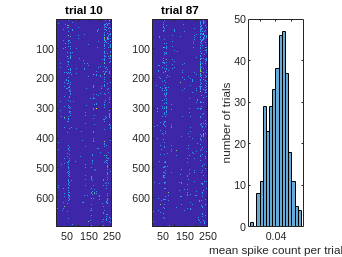

histogram(mean(spike_counts, [1,3]))
xlabel('mean spike count per trial')
ylabel('number of trials')

The spike counts of cells in the visual cortex is given below. 

Plot a histogram showing the mean spike count per trial for all cells and for cells only in the visual cortex. **Hint**- use `hold on... hold off` to display multiple histograms on the same plot

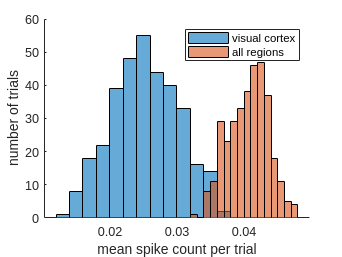

visual_cortex_spike_count = spike_counts(:,:,brain_areas=="visual cortex");
clf
hold on
histogram(mean(visual_cortex_spike_count, [1,3]), "DisplayName","visual cortex")
histogram(mean(spike_counts, [1,3]),"DisplayName","all regions")
hold off
legend
xlabel('mean spike count per trial')
ylabel('number of trials')

Remake the above plot, plotting the spike counts in the visual cortex and another brain area or areas of your choice.

Feel free to plot as many areas as you want!

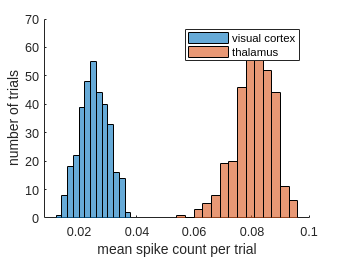

visual_cortex_spike_count = spike_counts(:,:,brain_areas=="visual cortex");
thalamus_spike_count = spike_counts(:,:,brain_areas=="thalamus");
clf
hold on
histogram(mean(visual_cortex_spike_count, [1,3]), "DisplayName","visual cortex")
histogram(mean(thalamus_spike_count, [1,3]),"DisplayName","thalamus")
hold off
legend
xlabel('mean spike count per trial')
ylabel('number of trials')

What is the mean spike count over time and trials? Name the result `mean_time_trials`

mean_time_trials=mean(spike_counts, [1,2]);

What dimensions does `mean_time_trials `have?

size(mean_time_trials)

ans =      1     1   698


Visualise mean_time_trials as a histogram. **Hint** - first you will need to reshape the matrix

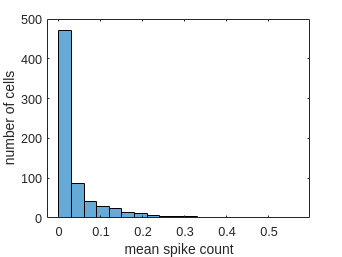

mean_array = reshape(mean_time_trials,1,[]);
histogram(mean_array)
xlabel("mean spike count")
ylabel("number of cells")

Which cell has the largest mean spike count over all trials and time bins?

[max_mean_spike_count,cell_num] = max(mean_array)

max_mean_spike_count = 0.5537

cell_num = 604

Which brain area does this cell belong to?

brain_areas(cell_num)

ans = "thalamus"

Which brain area hosts the cell that spiked the least?

[min_mean_spike_count,cell_num] = min(mean_array)

min_mean_spike_count = 0

cell_num = 6

brain_areas(cell_num)

ans = "visual cortex"

## Masking: Spike Count Analysis with Trial-level Categorical Variables

As we have seen before, in addition to brain area, we also have access to several categorical variables such as response type and stimulus contrast level. Let's see whether the pattern of neural activity would change for different values of these categorical variables.

Let's start by turning the spike counts into firing rates.

dt = 0.01;
firing_rate = spike_counts/dt;

**Example Exercise:** Plot the mean firing rate (averaged across neurons and trials) over time, taking all neurons.

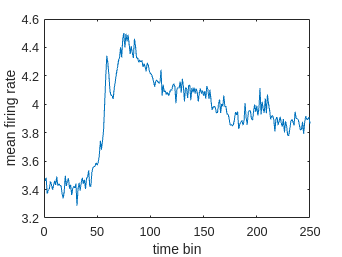

plot(mean(firing_rate, [2,3]))
xlabel('time bin')
ylabel('mean firing rate')

**Exercises**

Plot the mean firing rate only for trials where the response type is -1. **Hint **- use the `response_types` variable

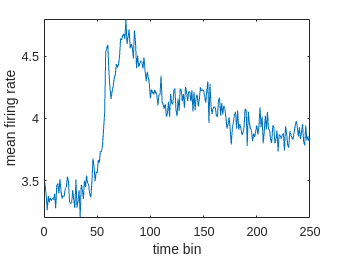

firing_rate_response_neg_1 = firing_rate(:,response_types==-1,:);
plot(mean(firing_rate_response_neg_1,[2,3]))

xlabel('time bin')
ylabel('mean firing rate')

Add to the previous plot the other two response types: one line for each response type(-1,0,+1). Did the population activity change between the response types?

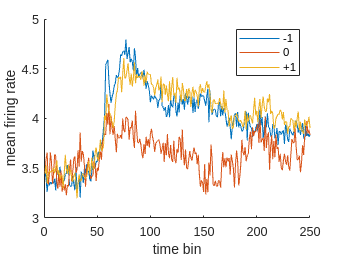

clf
hold on
plot(mean(firing_rate(:,response_types==-1,:),[2,3]), "DisplayName","-1")
plot(mean(firing_rate(:,response_types==0,:),[2,3]), "DisplayName","0")
plot(mean(firing_rate(:,response_types==1,:),[2,3]), "DisplayName","+1")
hold off
xlabel('time bin')
ylabel('mean firing rate')
legend

Make the same plot as the previous exercise, but only for neurons in the visual cortex. What do you notice?

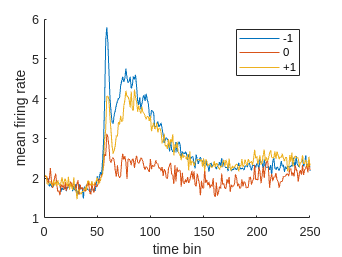

clf 
hold on
plot(mean(firing_rate(:,response_types==-1,brain_areas=="visual cortex"),[2,3]), "DisplayName","-1")
plot(mean(firing_rate(:,response_types==0,brain_areas=="visual cortex"),[2,3]), "DisplayName","0")
plot(mean(firing_rate(:,response_types==1,brain_areas=="visual cortex"),[2,3]), "DisplayName","+1")
hold off
xlabel('time bin')
ylabel('mean firing rate')
legend

Using subplots, create four plots in a single figure, each plotting  showing the the analysis in the previous exercise for a different brain  area. Specify the brain area in the title.

Below is an example of how to use subplots.

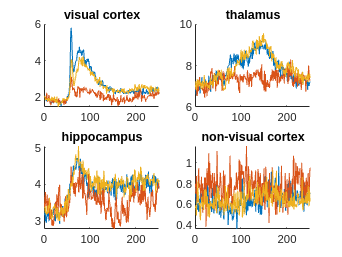

clf
subplot(2,2,1)
region = "visual cortex";
hold on
plot(mean(firing_rate(:,response_types==-1,brain_areas==region),[2,3]), "DisplayName","-1")
plot(mean(firing_rate(:,response_types==0,brain_areas==region),[2,3]), "DisplayName","0")
plot(mean(firing_rate(:,response_types==1,brain_areas==region),[2,3]), "DisplayName","+1")
title(region)
hold off

subplot(2,2,2)
region = "thalamus";
hold on
plot(mean(firing_rate(:,response_types==-1,brain_areas==region),[2,3]), "DisplayName","-1")
plot(mean(firing_rate(:,response_types==0,brain_areas==region),[2,3]), "DisplayName","0")
plot(mean(firing_rate(:,response_types==1,brain_areas==region),[2,3]), "DisplayName","+1")
title(region)
hold off

subplot(2,2,3)
region = "hippocampus";
hold on
plot(mean(firing_rate(:,response_types==-1,brain_areas==region),[2,3]), "DisplayName","-1")
plot(mean(firing_rate(:,response_types==0,brain_areas==region),[2,3]), "DisplayName","0")
plot(mean(firing_rate(:,response_types==1,brain_areas==region),[2,3]), "DisplayName","+1")
title(region)
hold off

subplot(2,2,4)
region = "non-visual cortex";
hold on
plot(mean(firing_rate(:,response_types==-1,brain_areas==region),[2,3]), "DisplayName","-1")
plot(mean(firing_rate(:,response_types==0,brain_areas==region),[2,3]), "DisplayName","0")
plot(mean(firing_rate(:,response_types==1,brain_areas==region),[2,3]), "DisplayName","+1")
title(region)
hold off